## Spherical Cap

The sphere of radius R cm and  density p_e g/cm^3 is submerged in seawater. The spere floats as long as its density is less than the seawater density, which is approximately p_a=1,027 gr/cm^3. 

We should find the height (h) of the portion of the float that is below the water.

According to Archimedes' Principle, the buoyancy force action on an object that is partially submerged in a fluid is equal to the weight of the fluid that is displaced by the proportion of the object that is submerged.

**Equations: **

- The spherical cap volume of heigh h is:

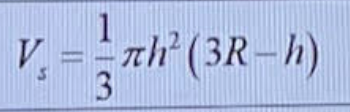 [1]

- The buoyance force is:

 [2]

- The difference betweent he buoyancy force F_g and the sphere weight F_g is:

 [3]

- The portion of the float that is submerged is obtained when the mass of the float equates the mass of the water that is displaced, this equation given by:

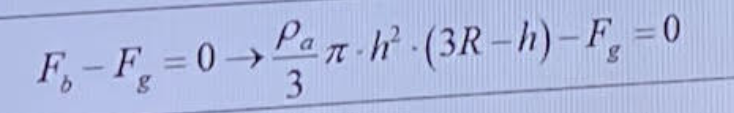 [4]

Solve for h in [4] using the following data: 

- R = 30 cm

- F_g = 4.5 N

- p_a = 1.027 g/l

- epsilon = 10^(-7)

**a. Solve the cubic equation (4) analytically. There are different approaches such as Cordano's method or Vieta substitution. **

I haven't worked with those methods previously, hence I'm providing a graphical solution with two known roots that can be used to proof-check the answer. 

p_a = 1.027

p_a = 1.0270

R = 30

R = 30

F_g = 4.5

F_g = 4.5000

sphere_cap = @(x) ((p_a / 3) * pi * x^2) * ((3 * R) - x) - F_g

sphere_cap = function_handle with value:
    @(x)((p_a/3)*pi*x^2)*((3*R)-x)-F_g


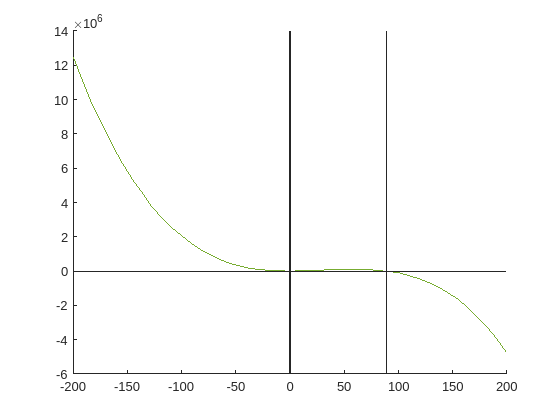

yline(0); hold on;
xline(-0.2154)
xline(0.2159)
xline(89);
fplot(sphere_cap, [-200, 200]); hold off

**b.  Solve the question with the iterative algorithm shown below**

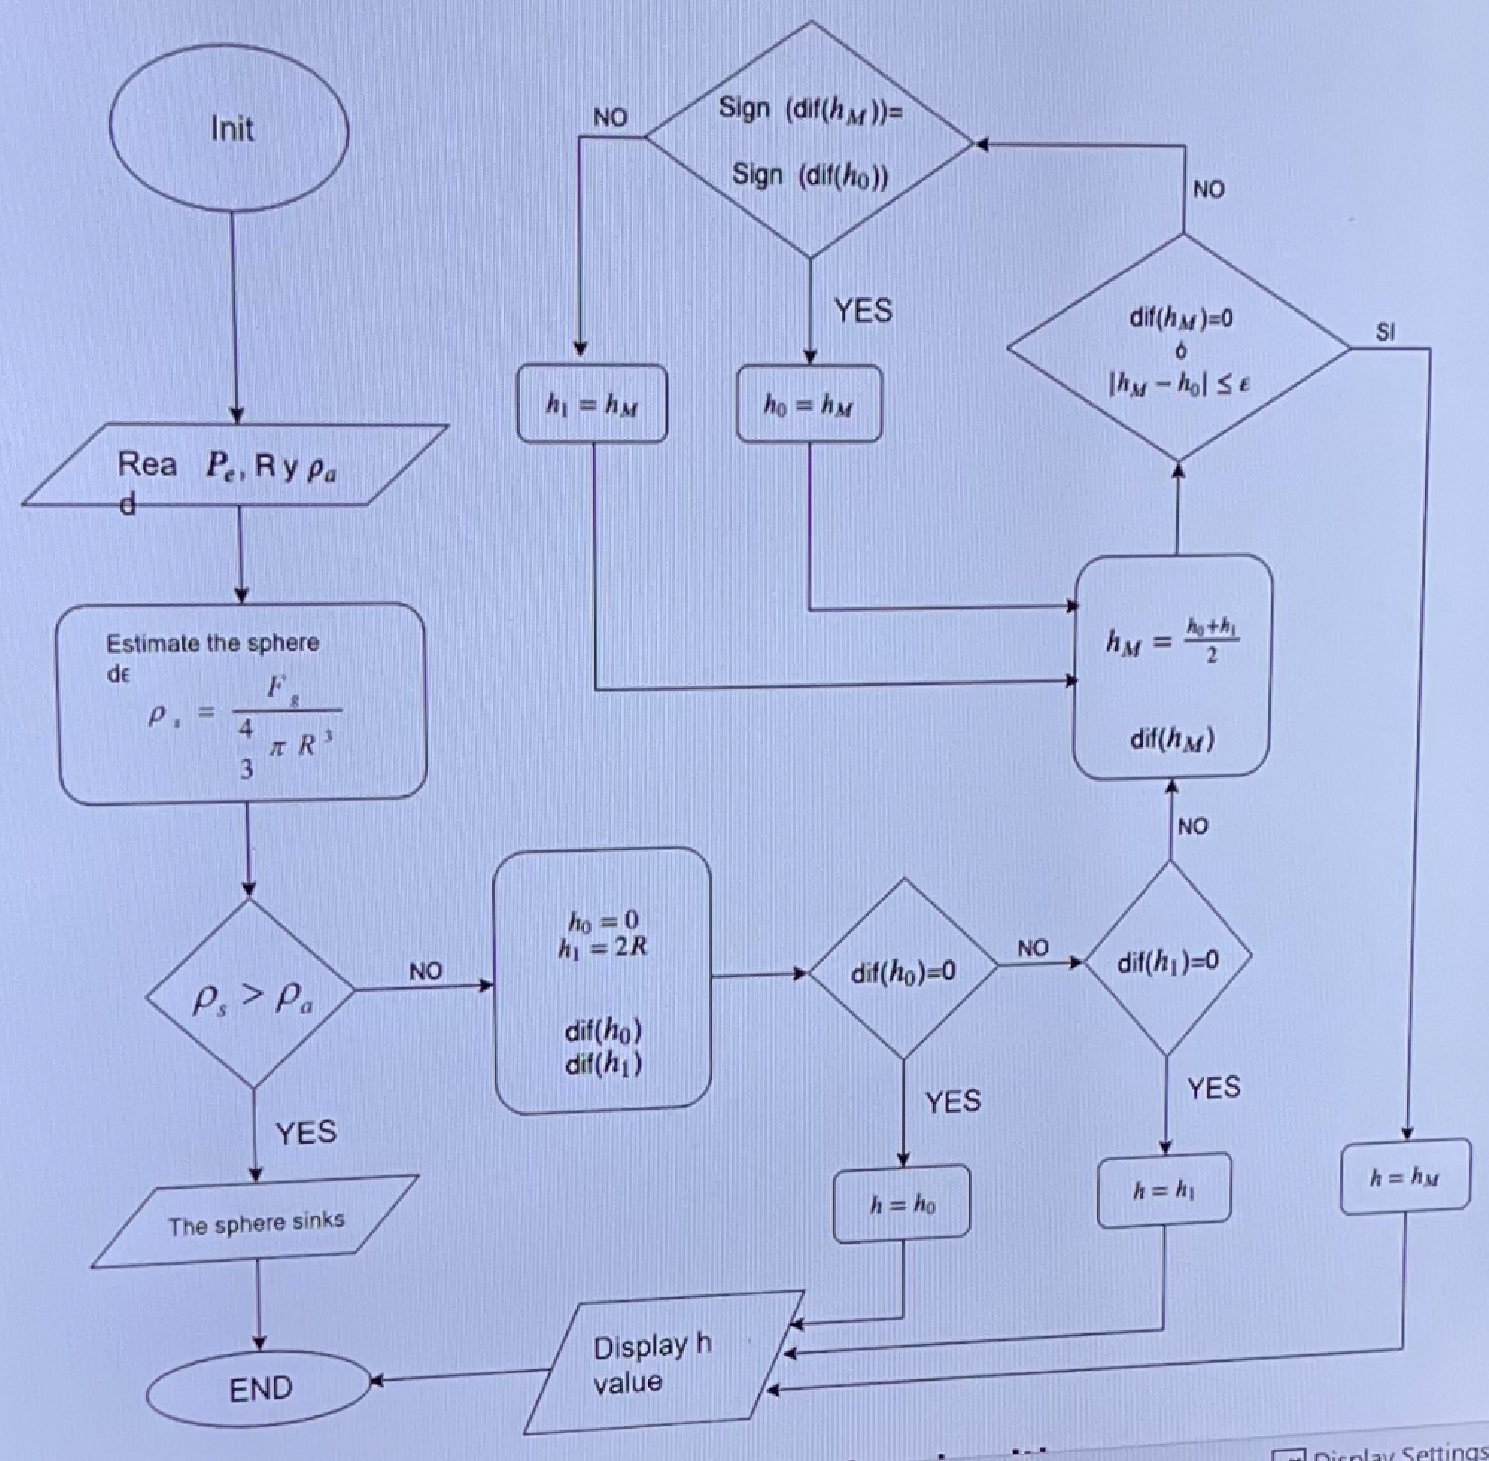

Initialize all required variables

R = 30

R = 30

p_e = 1.0

p_e = 1

p_a = 1.027

p_a = 1.0270

F_g = 4.5

F_g = 4.5000

epsilon = 10^(-7)

epsilon = 1.0000e-07

Note, that the internal loop essentially performs the bisection method (https://en.wikipedia.org/wiki/Root-finding_algorithms) of numerically finding the roots of an equation.

sphere_cap_pipeline(R, p_a, F_g, epsilon)

Not sinking, find h


h_m = 30

h_m = 15

h_m = 7.5000

h_m = 3.7500

h_m = 1.8750

h_m = 0.9375

h_m = 0.4688

h_m = 0.2344

h_m = 0.1172

    0.1172



**c. Solve the cubic equation using the Newton Raphson algorithm**

Note that the root found is dependent upon the initial value of h given. 

If you give the following h-values, you will receive all three roots [-10, 0, 80]

h_init = 80

h_init = 80

h_final = newton_raphson(h_init, R, p_a, F_g, epsilon)

h_current = 89.9995

h_current = 89.9995

h_final = 89.9995

**d. Solve the equation with fzero**

fzero only returns a single root dependent on the initial value. 

Initial values giving different roots include h_init = [0, 1, 10] each generates a unique root

h_init = 1

h_init = 1

h = fzero(sphere_cap, h_init)

h = 0.2159

**e. Solve the equation with the solve command availabe in the Symbolic Toolbox.**

syms x

sphere_cap_eq = ((p_a / 3) * pi * x^2) * ((3 * R) - x) - F_g == 0

$$sphere\_cap\_eq = -\frac{1027\,\pi \,x^{2}\,\left(x-90\right)}{3000}-\frac{9}{2}=0$$

h = solve(sphere_cap_eq, x, 'Real', true) 

$$h = \left(\begin{array}{c} \mathrm{root}\left(1027\,\pi \,z^{3}-92430\,\pi \,z^{2}+13500,z,1\right)\\ \mathrm{root}\left(1027\,\pi \,z^{3}-92430\,\pi \,z^{2}+13500,z,2\right)\\ \mathrm{root}\left(1027\,\pi \,z^{3}-92430\,\pi \,z^{2}+13500,z,3\right) \end{array}\right)$$

## Calculation of Trigonometric Functions

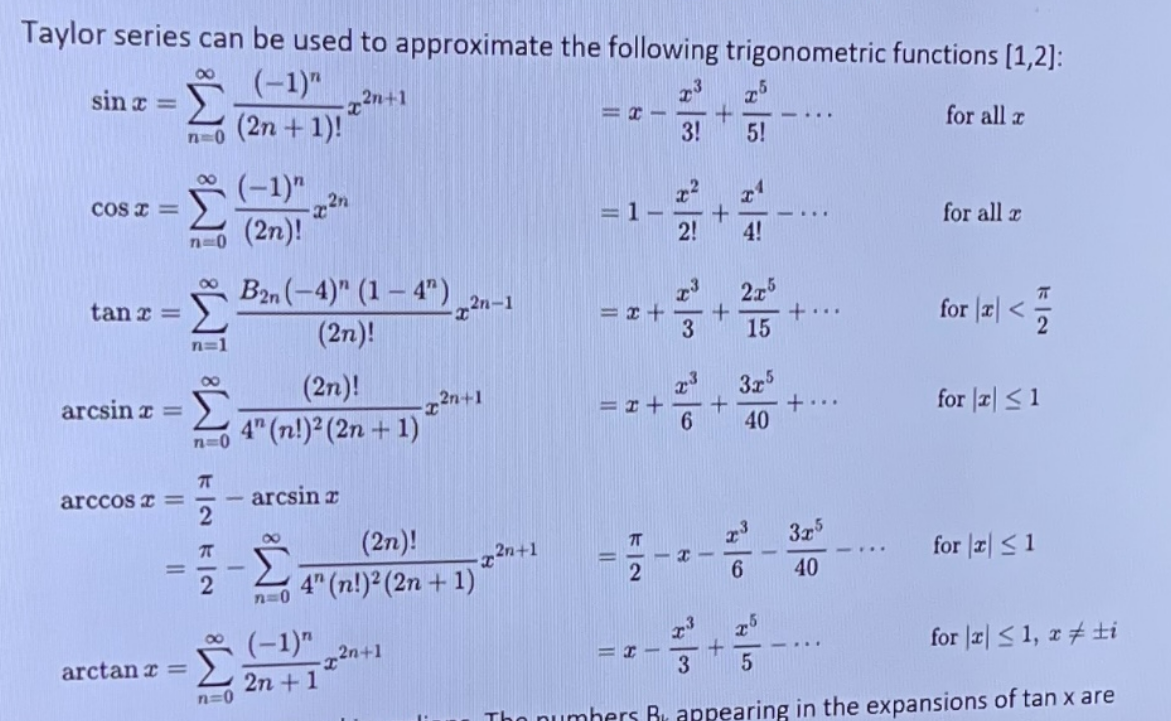

- All angles are expressed in Radians

- The numbers B_k appearing in the expansions of tanx are the Bernoulli numbers. 

- These series approximations and CORDIN are used in computers for finding the value of trigonometric functions. 

**A. Plot the principle branches of sin^(-1) (x), cos^(-1) (x), and tan^(-1) (x).**

Here are two great links explaining the concept of a principle value branch. The below notes are derived from these reousrces:

- [https://youtu.be/cOttZmdk-gk](https://youtu.be/cOttZmdk-gk) 

- [https://www.ck12.org/na/inverse-trigonometric-functions-and-principal-value-branch-1/lesson/Inverse-Trigonometric-Functions-xii-maths/](https://www.ck12.org/na/inverse-trigonometric-functions-and-principal-value-branch-1/lesson/Inverse-Trigonometric-Functions-xii-maths/) 

The range of the inverse trigonometric function is is called the principle value branch. 

Take for example the function sin(x):

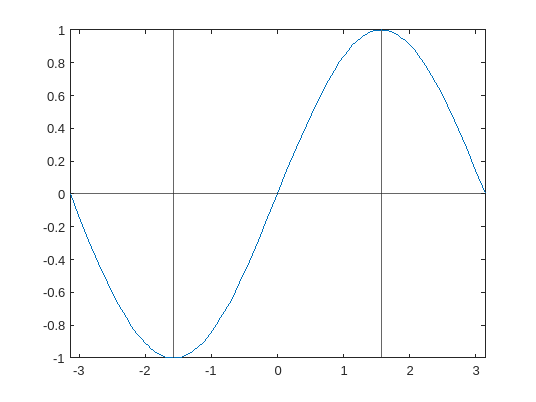

fplot(@(x) sin(x), [-pi, pi]); hold on;
xline(-pi/2)
xline(pi/2);
yline(0); hold off;

The range of sin(x): [-1, 1]. 

In order to create an inverse function, a restriction is required in order to make sin(x) a one-to-one function that allows for the full range of the function. 

The domain of sin(x): [- pi/2, pi/2]. 

Now plotting the inverse function sin^-1(x)

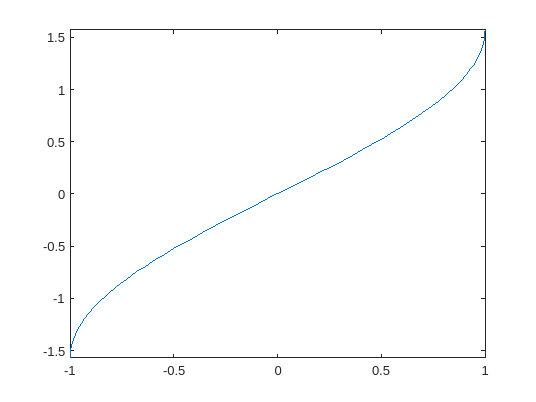

fplot(@(x) asin(x), [-1, 1])

Inverse domain: [-1, 1]

Inverse range: [-pi/2, pi/2]

In the inverse plot above, we can see that the domain of the inverse function is equal to the range of the standard function. Hence the prinicple branch of the inverse of sin(x) is **[-pi/2, pi/2].**

Using the above information we can follow the same procedure for the inverse of both cos(x) and tan(x)

**cos(x):**

Range: [-1, 1]

Domain: [0, pi]

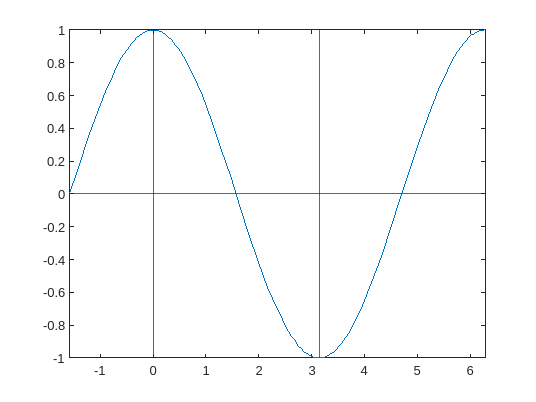

fplot(@(x) cos(x), [-pi/2, 2*pi]); hold on;
xline(0);
xline(pi);
yline(0); hold off;

Principle branch of the inverse of cos(x): [0, pi]

**tan(x)**

Range: (-inf, inf)

Domain (-pi/2, pi/2)

The domain boundaries are non-inclusive as they are the asymptotic boundaries of the tan(x) function.

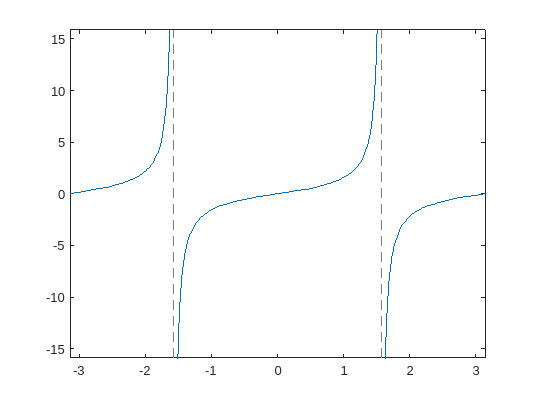

fplot(@(x) tan(x), [-pi, pi])

Principle branch of the inverse of tan(x): (-pi/2, pi/2)

**B. Write a matlab function called (trigTaylor) that takes three input arguments (x, numterms, type) and returns the value of the trigonometric functions evaluated at x. The input parameters are:**

- x: Number where is evaluated (for sin, cos, tan). It is an angle in Radians. 

- numterms: Number of terms used for the series approximation.

- type: Select the type of trigonometric function

trigTaylor(pi, 100, 'sin')

Sin


ans = 3.4663e-16

sin(pi)

ans = 1.2246e-16

## Functions (1)

function sphere_cap_pipeline(R, p_a, F_g, epsilon)
    % Estimate the sphere d_eps
    p_s = F_g / ((4/3) * pi * R^3);
    
   
    % Decision if sphere sinks
    if p_s > p_a
        disp('The Sphere sinks')
    else
        disp('Not sinking, find h')
        h_final = find_h(R, p_a, F_g, epsilon);
        disp(h_final)
    end
end

function [h_final] = find_h(R, p_a, F_g, epsilon)
    % Initialize h variables 
    h0 = 0;
    h1 = 2 * R; 

    % Create functions allowing dif calculation
    vol_h = @(h) ((1/3) * pi * h^2) * ((3 * R) - h);
    boyancy_f = @(h) p_a * vol_h(h);
    dif = @(h) boyancy_f(h) - F_g;

    % Check dif of h0
    if dif(h0) == 0
        h_final = h0;
    % Check dif of h1
    elseif dif(h1) == 0
        h_final = h1;
    % Both conditions fail, keep searching for h using internal loop in
    % diagram
    else
        h_final = h_calculation_internal_loop(h0, h1, dif, epsilon);
    end

end

function [h_value] = h_calculation_internal_loop(h0, h1, dif, epsilon)
    % Calculate initial h_m
    h_m = (h0 + h1) / 2;
    h_m_dif = dif(h_m);

    while abs(h_m - h0) > epsilon && h_m_dif ~= 0
        % Loop performs bisection method to find equation roots
        % Update values per loop to get closer to the roots
        h_m = (h0 + h1) / 2
        h_m_dif = dif(h_m);
        h0_dif = dif(h0);

        % Update lower bisection bound
        if sign(h_m_dif) == sign(h0_dif)
            h0 = h_m;
        % Update upper bisection bound
        else
            h1 = h_m;
        end
    end
    
    h_value = h_m;

end


function [h_current] = newton_raphson(h_init, R, p_a, F_g, epsilon)
    % Create functions allowing dif calculation
    syms h
    vol_h = ((1/3) * pi * h^2) * ((3 * R) - h);
    boyancy_f = p_a * vol_h;
    dif = boyancy_f - F_g;
    
    % Initialize h_prev and h_current for use in the loop
    h_prev = h_init;
    h_current = h_prev + 10;

    % Iteratively solve until finding h. 
    % Stopping conditions are when h0 and h_next are similar to each other
    % (within epsilon)
    while abs(h_prev - h_current) > epsilon
        % Update the prev h value to the h_current
        h_prev = h_current;

        % Calculate the derivative of h_current 
        derivative = diff(dif, h);
        h_current_derivative = double(subs(derivative,h_current));

        % Update the value of h_current using the Newton-Raphson equation
        h_current = h_current - (double(subs(dif, h_current)) / h_current_derivative)
    end
end

## Functions (2)

function [value] = trigTaylor(x, numterms, type)
    switch type
        case 'sin'
            disp('Sin')
            value = sin_taylor(x, numterms);
        case 'cos'
            disp('Cos')
            value = 0;
        case 'tan'
            disp('Tan')
            value = 0;
        case 'arcsin'
            disp('Arcsin')
            value = 0;
        case 'arccos'
            disp('Arccos')
            value = 0;
        case 'arctan'
            disp('Arctan')
            value = 0;
    end
end

function [value] = sin_taylor(x, n)
    value = 0;
    for i = 0:n
        value = value + (((-1)^i) / (factorial((2 * i) + 1))) * x^((2 * i) + 1);
    end
end